%clear all;
createSerialLink_zeroModify;
%Darstellung Verbindungsvektor linear
%Eingabe Startpunkt - Endpunkt

%p0 = [302 -25 277];
p1 = [302 -25 277];
p2 = [302 -25 327];
p3 = [302 0 362];
p4 = [302 25 327];
p5 = [302 25 277];
p6 = p2;
p7 = p4;
p8 = p1;
p9 = p5;

P=[p1; p2; p3; p4; p5; p6; p7; p8; p9]

P =      5   -25     5
   302   -25   327
   302     0   362
   302    25   327
   302    25   277
   302   -25   327
   302    25   327
     5   -25     5
   302    25   277


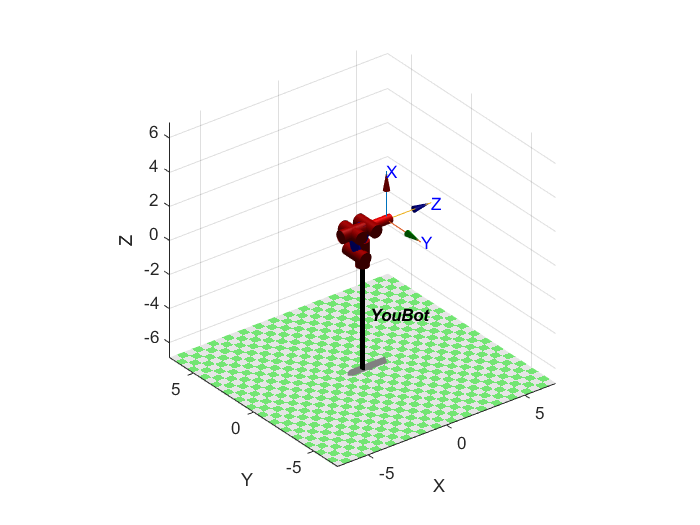

Error using Arbeitsraum_fertig (line 46)
Koordinaten sind nicht erreichbar, Koordinate zu nah


%Berechnung der Stützpunkte
a = 0 : 0.1 : 1;
a = transpose(a);
steps=size(a);
n=size(P);
for i=1:8
X = a*[P(i+1, :)-P(i,:)]+P(i,:);
Trajec_Array(:,:,i)=X;
end

for z=1:n-1
    for s =1:steps
        Arbeitsraum_fertig([Trajec_Array(s,1,z) Trajec_Array(s,2,z) Trajec_Array(s,3,z) 0 0]);
        Winkel=Inverskinematik_fertig([Trajec_Array(s,1,z) Trajec_Array(s,2,z) Trajec_Array(s,3,z) 0 0]);
        YouBot.plot(Winkel); 
    end
end